## Extract all the topics of interest from ROSBAG

% requirements - 

ROS toolbox

Mapping toolbox

rosbagReader.m script in same location as this file

clc
clear
% Each bag can be passed directly and named after the experiment
% the output of custom rosbagReader function is to generate dataset of all
% topics and combine all the readings in entire rosbag under one header

flat_concrete = rosbagReader('D:\husky_sysID\dataset_diffTerrain\concrete_2023-06-16-13-48-28.bag');

%bank_grass = rosbagReader('fsc_v_0.2_m_0002_2023-05-06-14-12-47.bag');

## **Plot example of Linear Acceleration in X with respect to relative time **

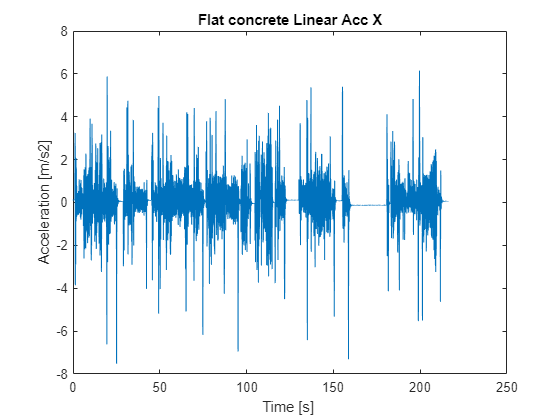

%flat_concrete.joint_states.Velocity
% Plotting each topic / any quantity becomes easier
ax = flat_concrete.gx5_imu_data.LinearAcceleration.X;
% reltime is relative time added to original struct it contains all
% timestamp - timestamp at 1 sec 
Reltime = flat_concrete.gx5_imu_data.RelTime;

fignum = 1;
figure(fignum)
plot(Reltime,ax)
title('Flat concrete Linear Acc X')
xlabel('Time [s] ')
ylabel('Acceleration [m/s2]')

## **Convert the GPS data to ENU-Carthesian coordinate frame**

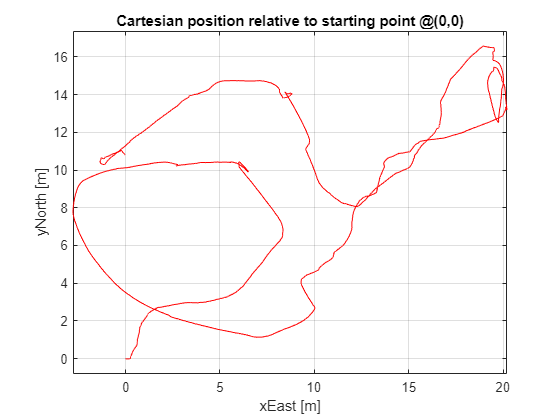

%Lets now plot navsatfix and coverted the quantities using geodetic to enu
%func and have a trajectory of robot

gpsLat = flat_concrete.piksi_multi_position_navsatfix_best_fix.Latitude;
gpsLon = flat_concrete.piksi_multi_position_navsatfix_best_fix.Longitude;
gpsAlt = flat_concrete.piksi_multi_position_navsatfix_best_fix.Altitude;
gpsReltime = flat_concrete.piksi_multi_position_navsatfix_best_fix.RelTime;
% Define the reference coordinates, corresponding to (0,0,0) coordinates
% let's pick the starting point of the trajectory according to the /bestfix
% topic
[xEastGPS, yNorthGPS, zUpGPS] = geodetic2enu(gpsLat ,gpsLon,gpsAlt,...
                                    gpsLat(1), gpsLon(1), gpsAlt(1),...
                                    wgs84Ellipsoid,"degrees");


fignum = 1;
figure(fignum)
plot(xEastGPS,yNorthGPS,'r');
grid on
axis equal
xlabel('xEast [m]');
ylabel('yNorth [m]');
title('Cartesian position relative to starting point @(0,0)');

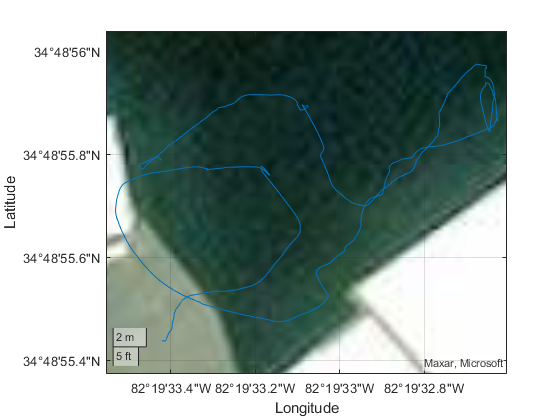

%% Lets see if the experiment area more clearly with satellite image
fignum = 1;
figure(fignum)
geoplot(gpsLat,gpsLon);
geobasemap satellite

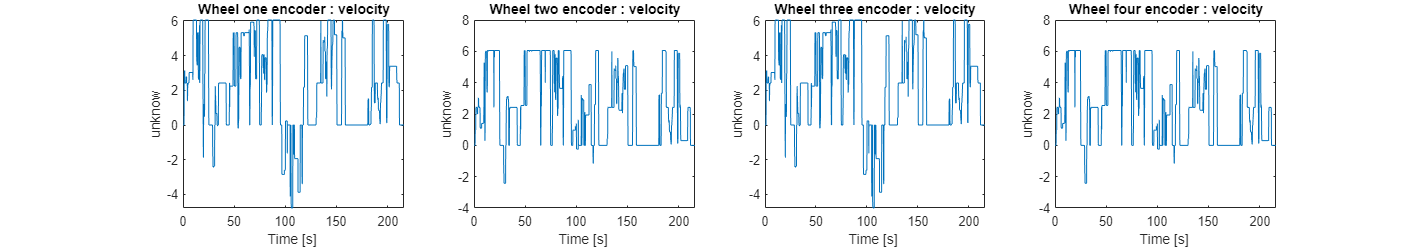

%Wheel Encoder data processing

%flat_concrete.joint_states.Velocity
% Plotting each topic / any quantity becomes easier
we = flat_concrete.joint_states.Velocity;

% reltime is relative time added to original struct it contains all
% timestamp - timestamp at 1 sec 
Reltime = flat_concrete.joint_states.RelTime;

%Wheel 1:

for i=1:length(we)
    w1(i) = we{i,1}(1,1);
    w2(i) = we{i,1}(2,1);
    w3(i) = we{i,1}(3,1);
    w4(i) = we{i,1}(4,1);
end



fignum = 1;
f = figure(fignum);

subplot(1,4,1)
plot(Reltime,w1)
title('Wheel one encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')

subplot(1,4,2)
plot(Reltime,w2)
title('Wheel two encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')

subplot(1,4,3)
plot(Reltime,w3)
title('Wheel three encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')

subplot(1,4,4)
plot(Reltime,w4)
title('Wheel four encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')

Two wheels on the same side are expected to have similar wheel velocites. Overlaying all the values on top of each other will help us identify those wheels

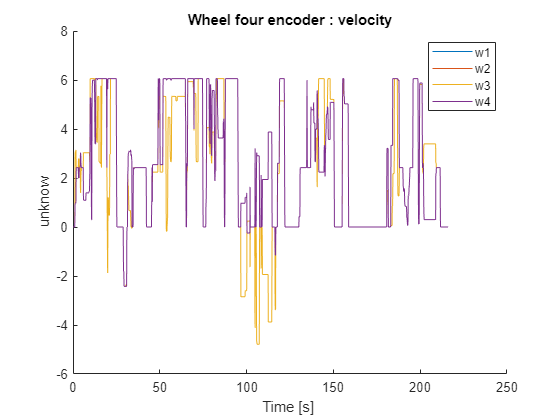


set(f,'Units','normalized','Position',[0 0 1.5 0.5])
% How same or different are all the wheel velocities

%fignum = 1;
f2 = figure();

hold on
plot(Reltime,w1)
title('Wheel one encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')


plot(Reltime,w2)
title('Wheel two encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')


plot(Reltime,w3)
title('Wheel three encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')


plot(Reltime,w4)
title('Wheel four encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')
legend('w1','w2','w3','w4')
hold off


set(f2,'Units','normalized','Position',[0 0 1.5 0.5])

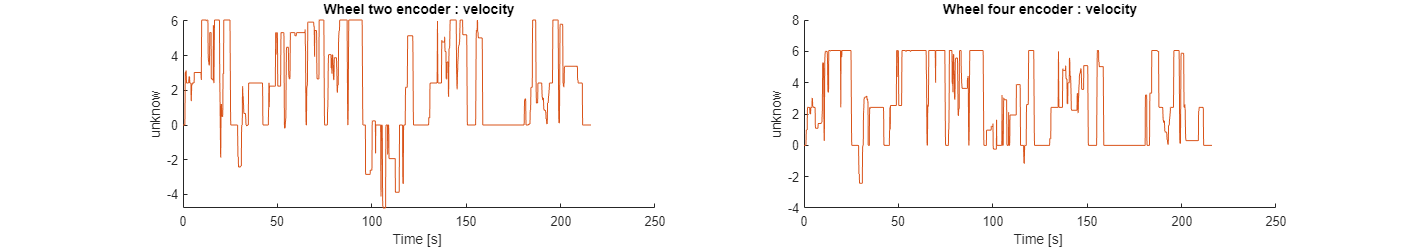



f3 = figure();

subplot(1,2,1)
hold on
plot(Reltime,w1)
title('Wheel one encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')


plot(Reltime,w3)
title('Wheel two encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')
hold off

subplot(1,2,2)
hold on
plot(Reltime,w2)
title('Wheel three encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')


plot(Reltime,w4)
title('Wheel four encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')
hold off

set(f3,'Units','normalized','Position',[0 0 1.5 0.5])

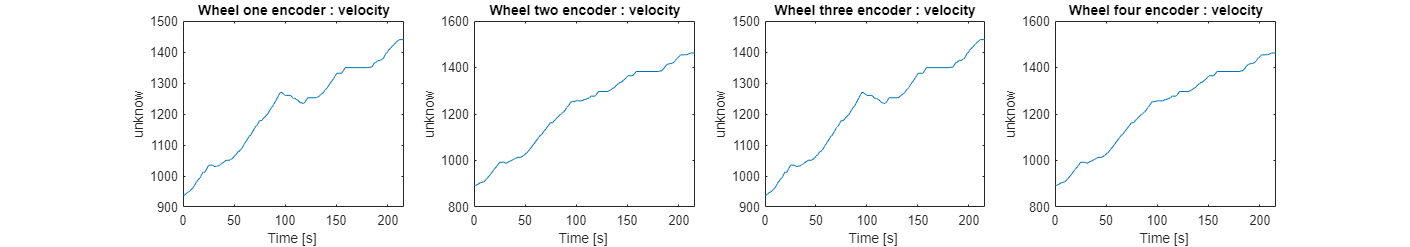

%Joint state position measurement

we_pos = flat_concrete.joint_states.Position;

% reltime is relative time added to original struct it contains all
% timestamp - timestamp at 1 sec 
Reltime = flat_concrete.joint_states.RelTime;

%Wheel 1:

for i=1:length(we_pos)
    w1p(i) = we_pos{i,1}(1,1);
    w2p(i) = we_pos{i,1}(2,1);
    w3p(i) = we_pos{i,1}(3,1);
    w4p(i) = we_pos{i,1}(4,1);
end



fignum = 1;
f = figure(fignum);

subplot(1,4,1)
plot(Reltime,w1p)
title('Wheel one encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')

subplot(1,4,2)
plot(Reltime,w2p)
title('Wheel two encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')

subplot(1,4,3)
plot(Reltime,w3p)
title('Wheel three encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')

subplot(1,4,4)
plot(Reltime,w4p)
title('Wheel four encoder : velocity')
xlabel('Time [s] ')
ylabel('unknow')